% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

%  
% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + Ci a b + Jp a b s  + Ji a b s)




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.48;  %effective length 
a = 18;           %nominal motor parameters
b = 0.003;        %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{9\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{80\,\left(s^{2}-\frac{327}{16}\right)\,\left(\frac{27\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{500\,\left(s+18\right)}+1\right)\,\left(s+18\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 

% p1 = -1 + 2*pi*i    % dominant pole pair
% p2 = -1 - 2*pi*i    % dominant pole pair 
% p3 = -10
% p4 = -8
% p5 = -8.

p1 = -0.35 + 0.357*i        % dominant pole pair

p1 = -0.3500 + 0.3570i

p2 = -0.35 - 0.357*i        % dominant pole pair

p2 = -0.3500 - 0.3570i

p3 = -0.5 + 10*i

p3 = -0.5000 + 10.0000i

p4 = -0.5 - 10*i     % dominant pole pair

p4 = -0.5000 - 10.0000i

p5 = -13               % dominant pole pair 

p5 = -13


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = \left(s+13\right)\,\left(s+\frac{1}{2}-10\,\mathrm{i}\right)\,\left(s+\frac{1}{2}+10\,\mathrm{i}\right)\,\left(s+\frac{7}{20}-\frac{357}{1000}\,\mathrm{i}\right)\,\left(s+\frac{7}{20}+\frac{357}{1000}\,\mathrm{i}\right)$$

exp_tgt_char_poly = expand(tgt_char_poly)

$$exp\_tgt\_char\_poly = s^{5}+\frac{147\,s^{4}}{10}+\frac{123299949\,s^{3}}{1000000}+\frac{693012143\,s^{2}}{500000}+\frac{3762326897\,s}{4000000}+\frac{1302984137}{4000000}$$


% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = \left(16\,s^{2}-327\right)\,\left(27\,\text{Ci}+27\,\mathrm{Ji}\,s+27\,\mathrm{Jp}\,s^{2}+9000\,s^{2}+500\,s^{3}\right)$$

$$d = 432\,\text{Ci}\,s^{2}-8829\,\mathrm{Ji}\,s-8829\,\text{Ci}+432\,\mathrm{Ji}\,s^{3}-8829\,\mathrm{Jp}\,s^{2}+432\,\mathrm{Jp}\,s^{4}+900\,\mathrm{Ki}\,s^{2}+900\,\mathrm{Kp}\,s^{3}-2943000\,s^{2}-163500\,s^{3}+144000\,s^{4}+8000\,s^{5}$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -8829\,\text{Ci} & -8829\,\mathrm{Ji} & 432\,\text{Ci}-8829\,\mathrm{Jp}+900\,\mathrm{Ki}-2943000 & 432\,\mathrm{Ji}+900\,\mathrm{Kp}-163500 & 432\,\mathrm{Jp}+144000 & 8000 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{8829\,\text{Ci}}{8000} & -\frac{8829\,\mathrm{Ji}}{8000} & \frac{27\,\text{Ci}}{500}-\frac{8829\,\mathrm{Jp}}{8000}+\frac{9\,\mathrm{Ki}}{80}-\frac{2943}{8} & \frac{27\,\mathrm{Ji}}{500}+\frac{9\,\mathrm{Kp}}{80}-\frac{327}{16} & \frac{27\,\mathrm{Jp}}{500}+18 & 1 \end{array}\right)$$

% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccccc} \frac{1302984137}{4000000} & \frac{3762326897}{4000000} & \frac{693012143}{500000} & \frac{123299949}{1000000} & \frac{147}{10} & 1 \end{array}\right)$$

% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)

$$roots\_target = \left(\begin{array}{c} -13.0\\ -0.5-10.0\,\mathrm{i}\\ -0.5+10.0\,\mathrm{i}\\ -0.35-0.357\,\mathrm{i}\\ -0.35+0.357\,\mathrm{i} \end{array}\right)$$



% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 1.6868e+03

Ki = double(solutions.Ki)

Ki = 1.5132e+04

Ji = double(solutions.Ji)

Ji = -852.2657

Jp = double(solutions.Jp)

Jp = -61.1111

Ci = double(solutions.Ci)

Ci = -295.1601


%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

$$aaa = \left(\begin{array}{cccccc} 325.7 & 940.6 & 1386.0 & 123.3 & 14.7 & 1.0 \end{array}\right)$$


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

$$check\_closed\_loop\_poles = \left(\begin{array}{c} -0.35-0.357\,\mathrm{i}\\ -0.35+0.357\,\mathrm{i}\\ -0.5-10.0\,\mathrm{i}\\ -0.5+10.0\,\mathrm{i}\\ -13.0 \end{array}\right)$$


% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )



% Plot impulse and step responses of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  4.254e41 s^8 + 1.391e43 s^7 + 8.428e43 s^6 - 6.434e44 s^5 - 2.022e45 s^4 + 7.34e45 s^3 + 2.494e45 s^2
  -----------------------------------------------------------------------------------------------------
  4.254e41 s^8 + 1.391e43 s^7 + 1.65e44 s^6 + 1.534e45 s^5 + 1.101e46 s^4 + 7.34e45 s^3 + 2.494e45 s^2
 
Continuous-time transfer function.



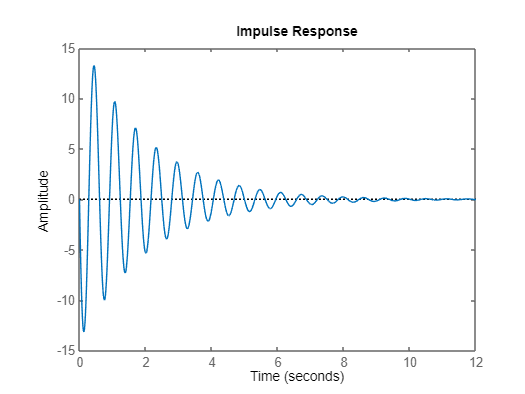

    figure (1)
    impulse(TFH);   %plot the impulse reponse

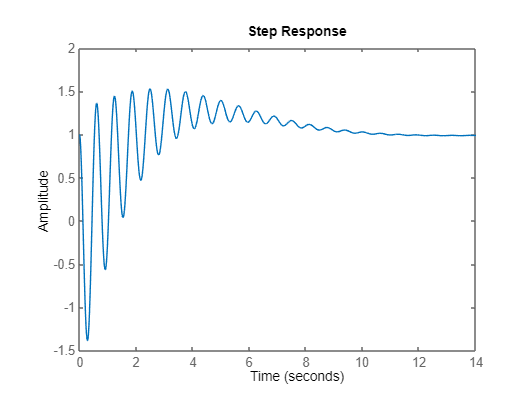

    figure(2)
    step(TFH)       %plot the step response